## Método de Newton-Raphson para optimización

Con el uso de segunda derivada dentro de la función, podemos obtener un punto crítico de la función

clear; clf;
f = @(x) -12-21.*x + 18.*x.^2 - 2.75.*x.^3;
fs = sym(f)

$$fs = -\frac{11\,x^{3}}{4}+18\,x^{2}-21\,x-12$$

df = diff(fs);
dfs = sym(df)

$$dfs = -\frac{33\,x^{2}}{4}+36\,x-21$$

puntosCriticos = roots([-33/4 36 -21])

puntosCriticos =     3.6701
    0.6936


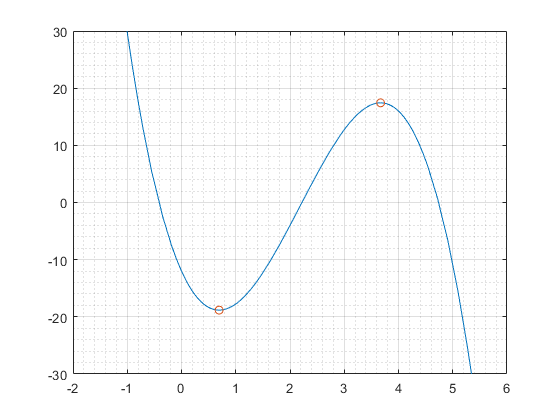

fplot(f);
grid on; grid minor; hold on;
axis([-2 6 -30 30]);
plot(puntosCriticos,f(puntosCriticos),'o'); hold off;

[raiz, iteraciones, fx] = NewtonRaphsonOptimizado(f, -1)

raiz = 0.6936

iteraciones = 7

fx = -18.8238

function [x, i, fx] = NewtonRaphsonOptimizado(f,x)
    max_iter = 53;
    tol = eps();
    
    fsym = sym(f);
    dfs1 = diff(fsym,1);
    dfs2 = diff(fsym,2);
    df1 = matlabFunction(dfs1);
    df2 = matlabFunction(dfs2);     
    
    i = 0;
    cond = true;
    while cond
        xn = x;
        ddx = -df1(x)/df2(x);
        x = xn + ddx;
        fx = f(x);
        
        i = i + 1;
        cond = abs(ddx/x) > tol && i < max_iter;
    end
end